# One-Sample T-Test Example

Babak Aliyari

Babak.aliyari.edu@gmail.com

#### **Define hypotheses:**

#### **Null Hypothesis (H0): Population mean = 100**

#### **Alternative Hypothesis (H1): Population mean ≠ 100**

# **Test if the sample mean equals 100:**


clear all;
close all;
clc;
cd('D:\0 Signal\AmarT');

% Generate sample data (normally distributed random values)
rng(42); % Set seed for reproducibility
n = 50; % Sample size
trueMean = 100;
trueStd = 15;
sampleData = trueStd * randn(n, 1) + trueMean;

% Define hypotheses
% Null Hypothesis (H0): Population mean = 100
% Alternative Hypothesis (H1): Population mean ≠ 100

% Test if the sample mean equals 100
hypothesizedMean = 100;
[h, p, ci, stats] = ttest(sampleData, hypothesizedMean);

% Display results
fprintf('One-Sample T-Test Results:\n');

One-Sample T-Test Results:


fprintf('Hypothesized mean: %.2f\n', hypothesizedMean);

Hypothesized mean: 100.00


fprintf('Sample mean: %.2f\n', mean(sampleData));

Sample mean: 100.46


fprintf('t-statistic: %.4f\n', stats.tstat);

t-statistic: 0.2255


fprintf('Degrees of freedom: %d\n', stats.df);

Degrees of freedom: 49


fprintf('p-value: %.4f\n', p);

p-value: 0.8225


fprintf('95%% Confidence Interval: [%.2f, %.2f]\n', ci(1), ci(2));

95% Confidence Interval: [96.39, 104.53]



% Interpret results
if h == 1
    fprintf('Conclusion: Reject H0 - Sample mean differs significantly from %.2f\n', hypothesizedMean);
else
    fprintf('Conclusion: Fail to reject H0 - No significant difference from %.2f\n', hypothesizedMean);
end

Conclusion: Fail to reject H0 - No significant difference from 100.00


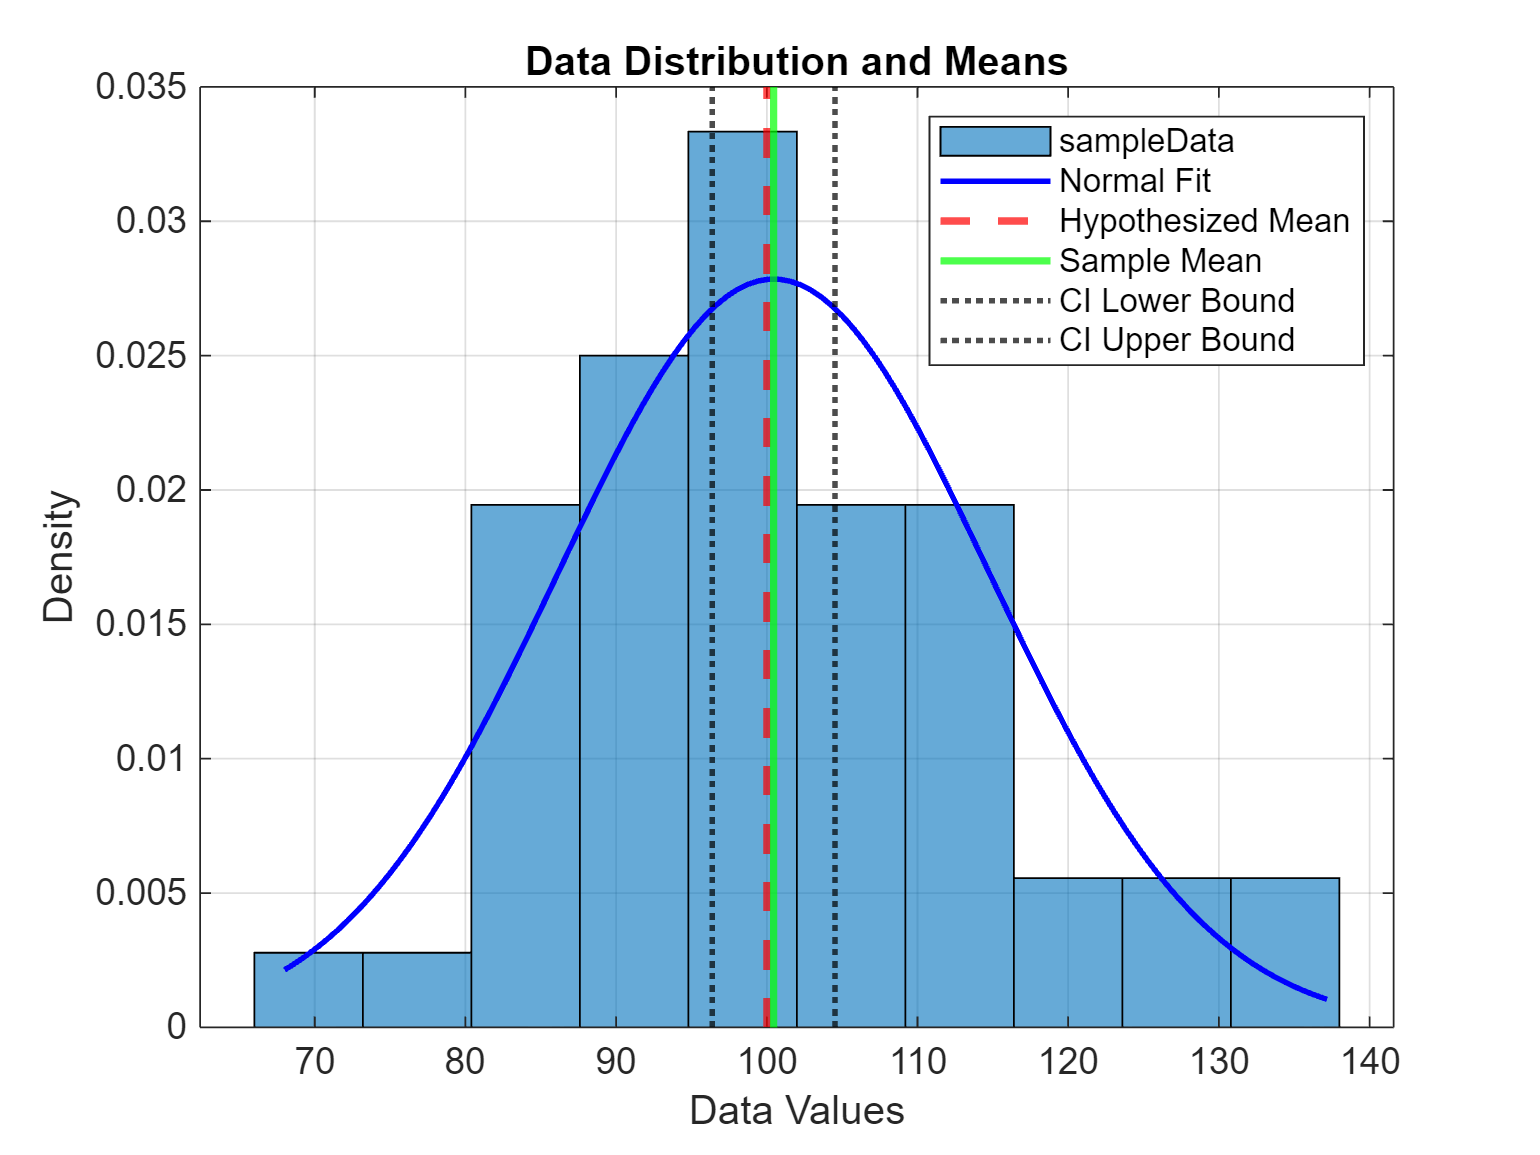


%% Create visualizations
figure;

% Plot 1: Histogram with normal distribution overlay
histogram(sampleData, 10, 'Normalization', 'pdf');
hold on;
% Overlay normal distribution
x_values = linspace(min(sampleData), max(sampleData), 100);
pdf_values = normpdf(x_values, mean(sampleData), std(sampleData));
plot(x_values, pdf_values, 'b-', 'LineWidth', 1.5, 'DisplayName', 'Normal Fit');
% Vertical lines
xline(hypothesizedMean, 'r--', 'LineWidth', 2, 'DisplayName', 'Hypothesized Mean');
xline(mean(sampleData), 'g-', 'LineWidth', 2, 'DisplayName', 'Sample Mean');
xline(ci(1), 'k:', 'LineWidth', 1.5, 'DisplayName', 'CI Lower Bound');
xline(ci(2), 'k:', 'LineWidth', 1.5, 'DisplayName', 'CI Upper Bound');
xlabel('Data Values');
ylabel('Density');
title('Data Distribution and Means');
legend;
grid on;

The shape of your sample data distribution'

The sample mean (green solid line)'

hypothesized population mean (red dashed line)

The 95% confidence interval bounds (black dotted lines)

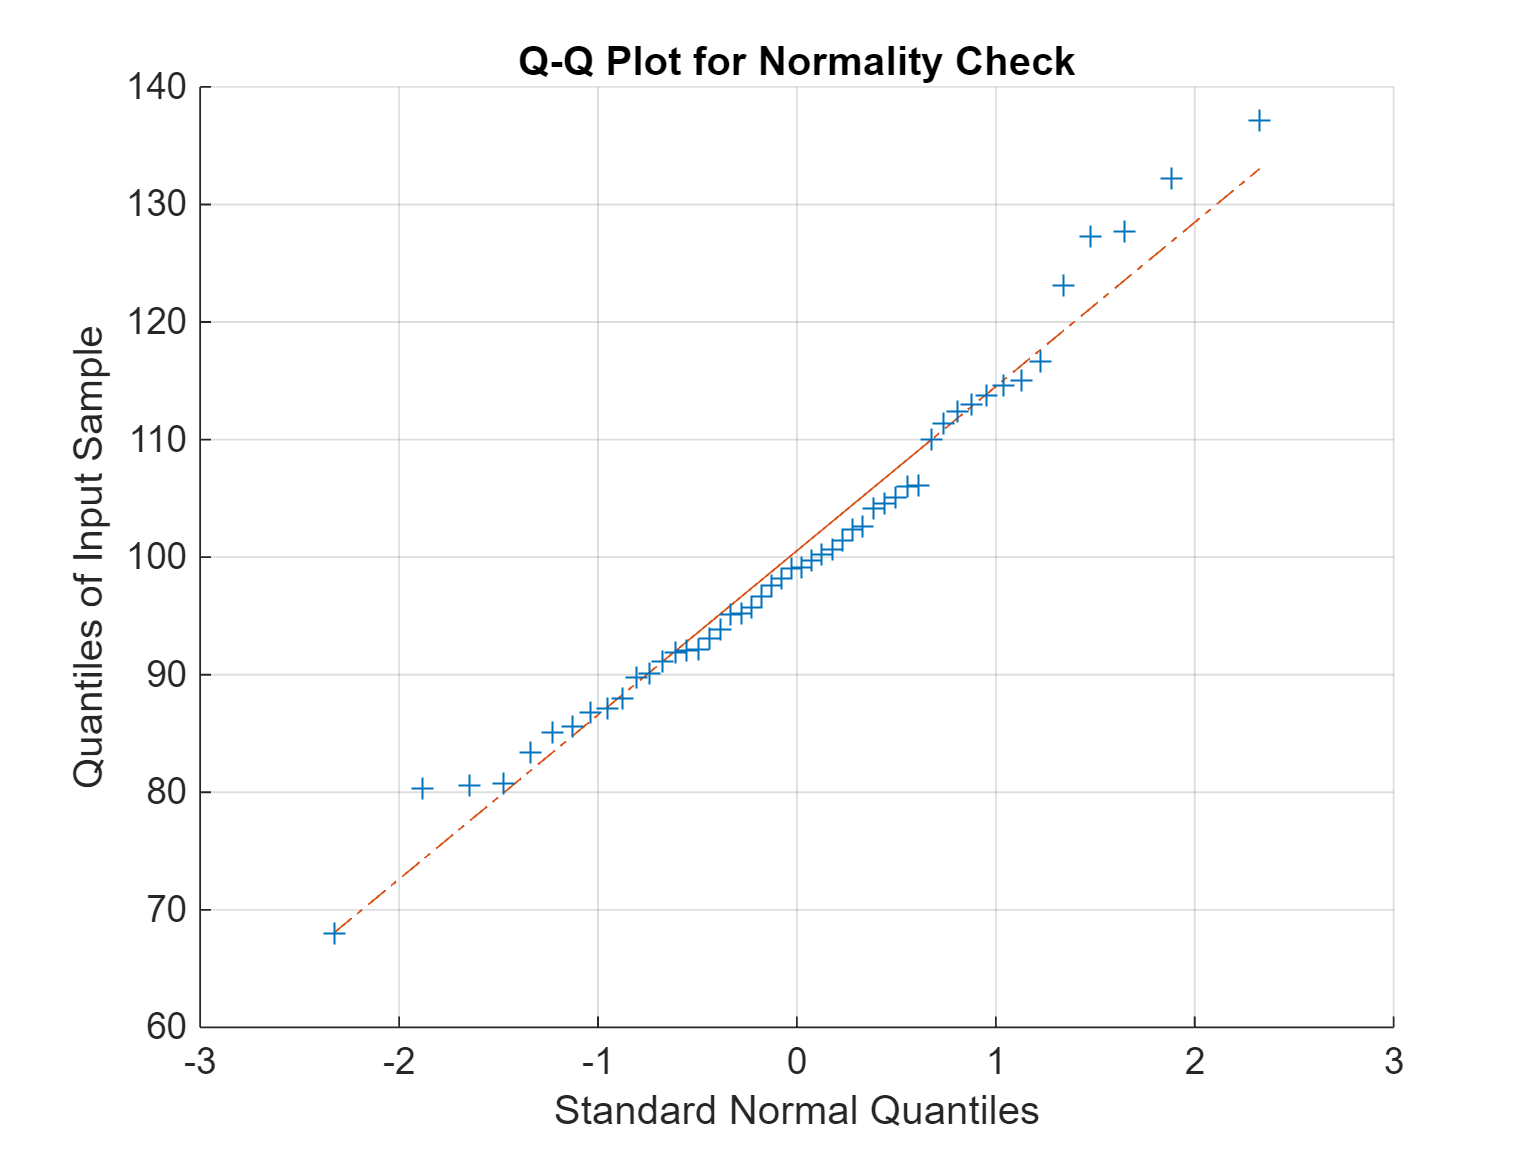

% Plot 2: Q-Q Plot (unchanged)
figure;
qqplot(sampleData);
title('Q-Q Plot for Normality Check');
grid on;

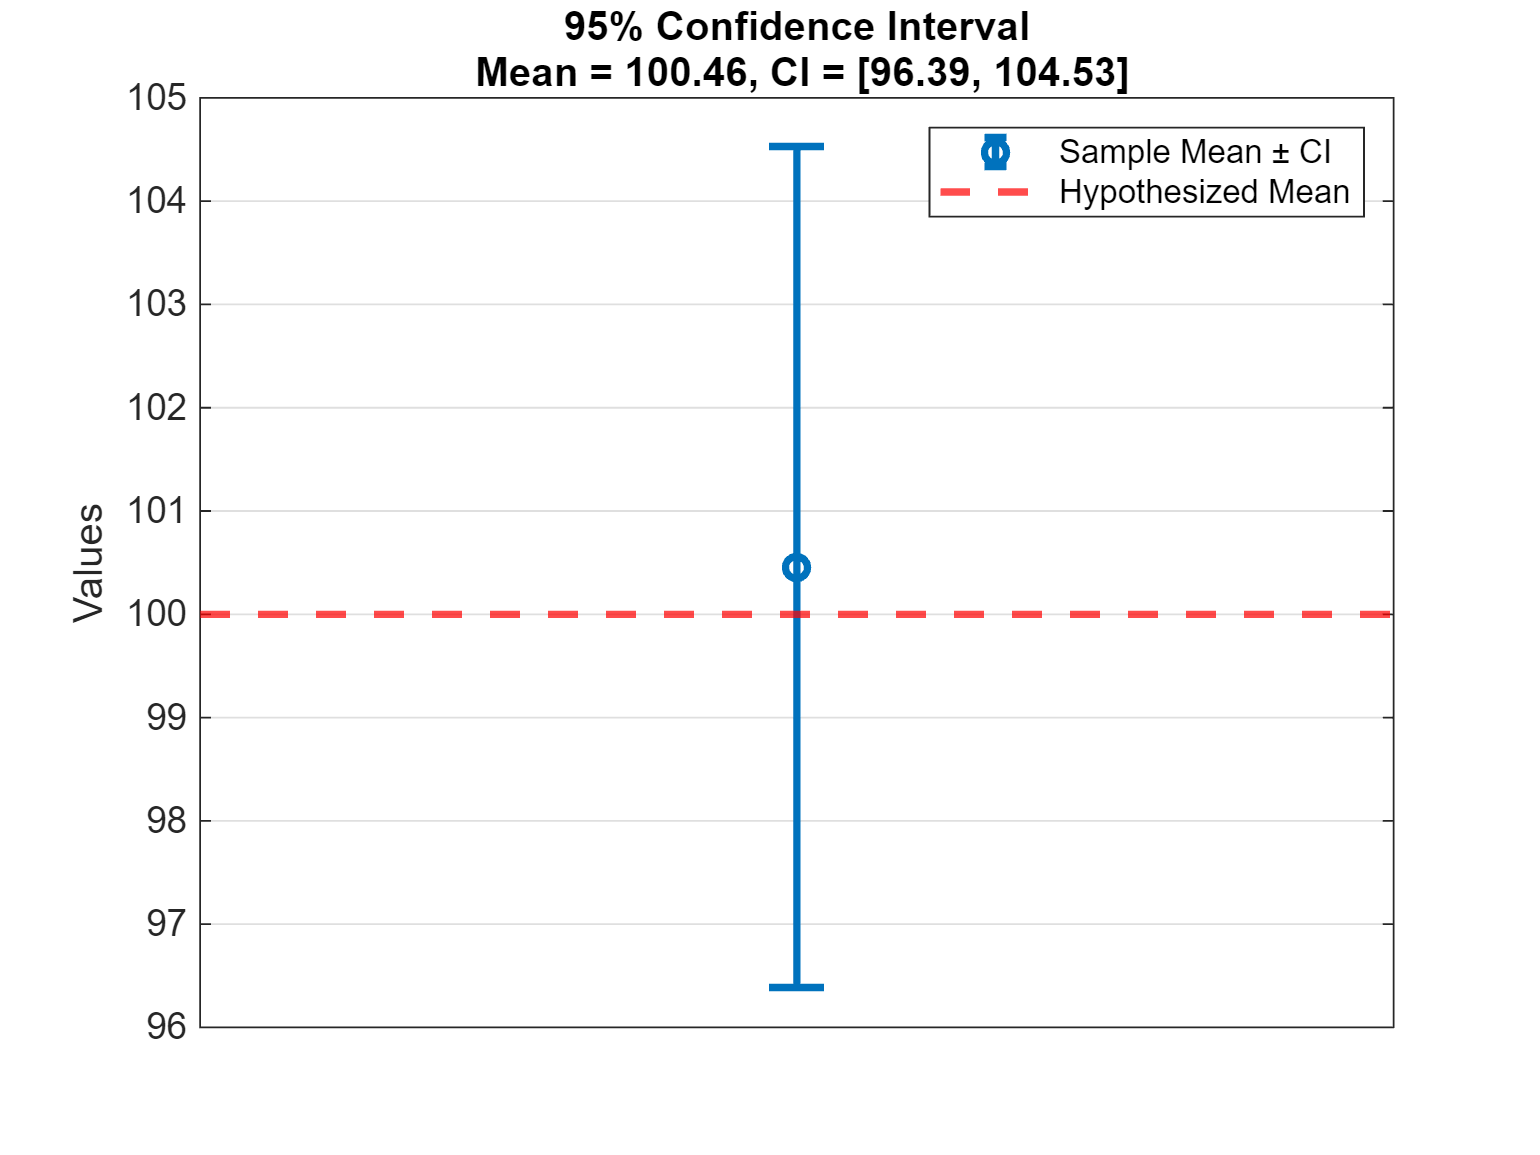

% Plot 3: Confidence interval visualization (corrected)
figure;
mean_val = mean(sampleData);
ci_halfwidth = (ci(2)-ci(1))/2;
errorbar(1, mean_val, ci_halfwidth, 'o', 'LineWidth', 2, 'CapSize', 15);
hold on;
yline(hypothesizedMean, 'r--', 'LineWidth', 2, 'DisplayName', 'Hypothesized Mean');
set(gca, 'XTick', []);
ylabel('Values');
title(sprintf('95%% Confidence Interval\n Mean = %.2f, CI = [%.2f, %.2f]', ...
    mean_val, ci(1), ci(2)));
legend('Sample Mean ± CI', 'Hypothesized Mean');
grid on;
xlim([0.5 1.5]);

The sample mean (point with error bars)'

The 95% confidence interval (range covered by the error bars)

The hypothesized mean (red dashed line)

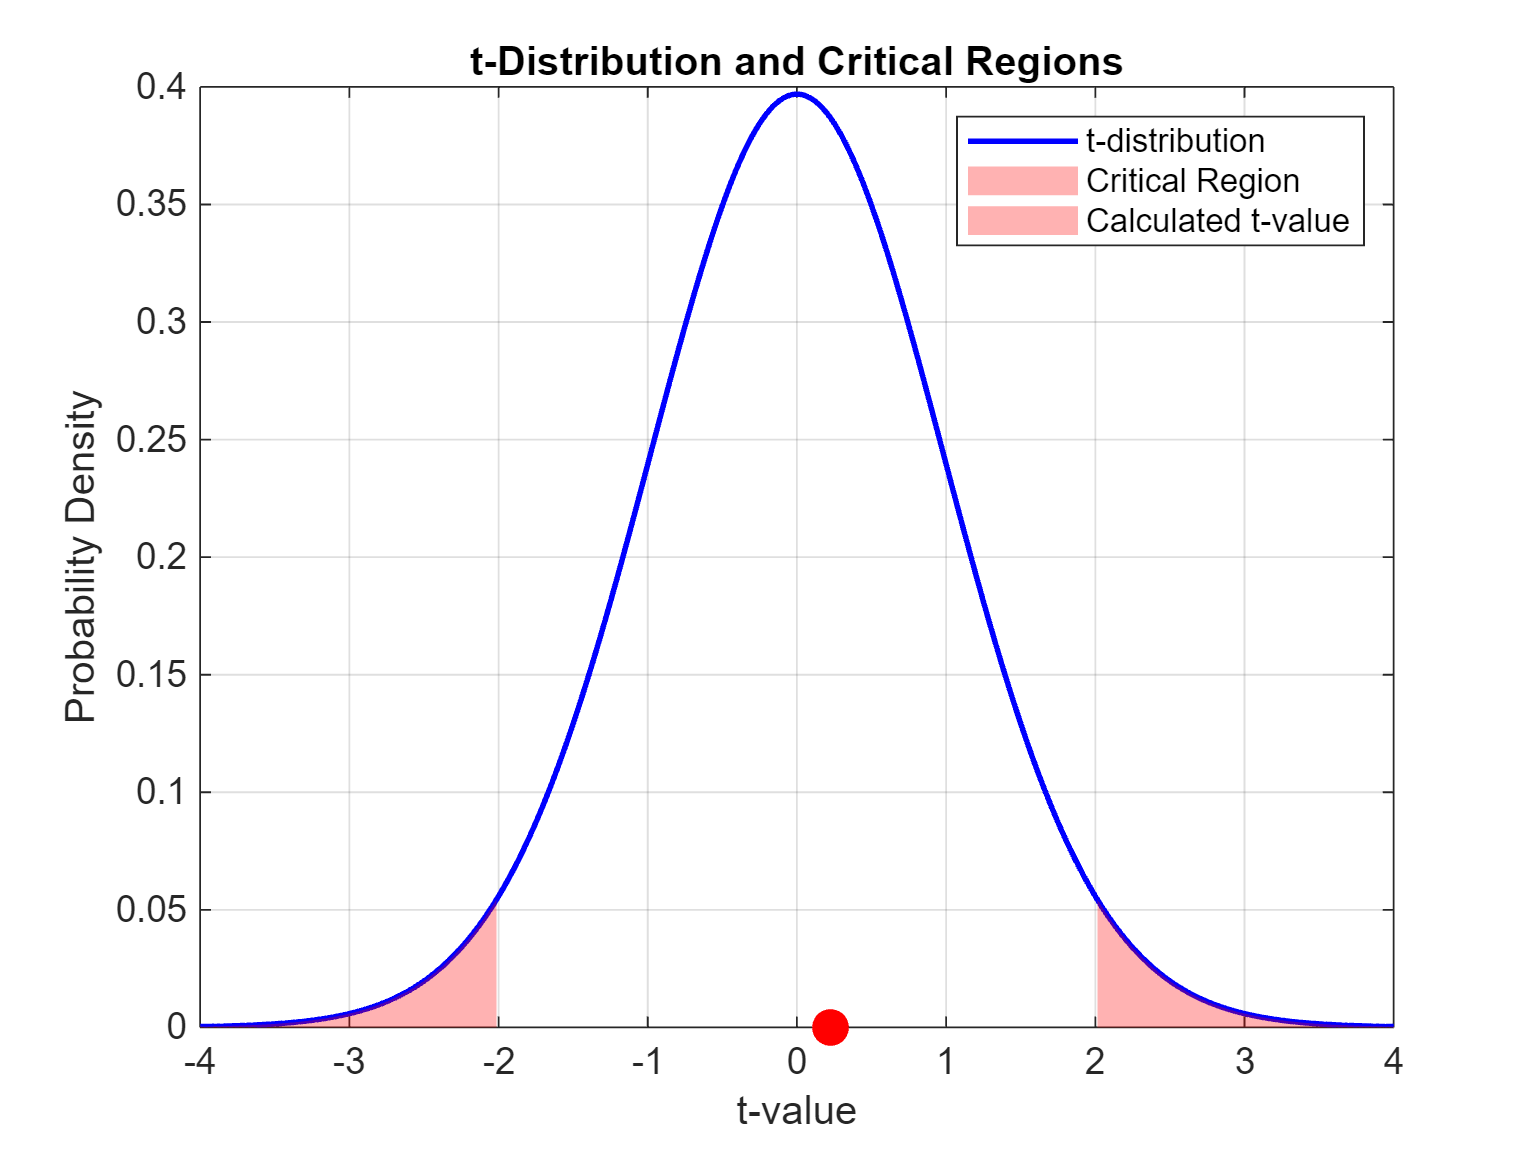


% Plot 4: t-distribution with critical region (corrected)
figure;
x = linspace(-4, 4, 1000);
t_dist = tpdf(x, stats.df);
plot(x, t_dist, 'b', 'LineWidth', 1.5);
hold on;
% Critical values for two-tailed test
alpha = 0.05;
t_critical = tinv(1 - alpha/2, stats.df);
% Shade right tail
idx_right = x >= t_critical;
fill([x(idx_right) fliplr(x(idx_right))], ...
     [t_dist(idx_right) zeros(1, sum(idx_right))], 'r', 'FaceAlpha', 0.3, 'EdgeColor', 'none');
% Shade left tail
idx_left = x <= -t_critical;
fill([x(idx_left) fliplr(x(idx_left))], ...
     [t_dist(idx_left) zeros(1, sum(idx_left))], 'r', 'FaceAlpha', 0.3, 'EdgeColor', 'none');
% Mark calculated t-statistic
plot(stats.tstat, 0, 'ro', 'MarkerSize', 8, 'LineWidth', 2, 'MarkerFaceColor', 'r');
title('t-Distribution and Critical Regions');
xlabel('t-value');
ylabel('Probability Density');
legend('t-distribution', 'Critical Region', 'Calculated t-value');
grid on;

What it shows in our t-test context:

- The blue curve shows the t-distribution with your specific degrees of freedom

- The red shaded areas represent the critical regions where we would reject the null hypothesis

- The red dot shows where your calculated t-value falls on this distribution

How to interpret it:

- If the red dot falls in the red shaded areas, your result is statistically significant (p < 0.05)

- The further the t-value is from zero, the stronger the evidence against the null hypothesis

- The shape of the t-distribution becomes closer to normal as degrees of freedom increase